## Parameters

on_GPU = false;
T = 40; % sec
N = 200; % number of neurons 200
input_Hz = 50; % Hz
conn_prob_input2E = 0.1; % a.u.
conn_strength_input2E = 1; % a.u.
conn_prob_E2E = 0.25; % a.u.
conn_strength_E2E = 1; % a.u.
STDP_learning_rate_E2E = 0.05; % a.u. (STDP)

plasticity_type = "mulSTDP";

plot_synapses = false;
plot_Vm = false;
plot_spikes = false;
plot_refractoriness = false;
plot_weights = true;
plot_Hz = true;
plot_stimulation = true;
plot_STDP_traces = false;
plot_resource_pool = true;
plot_digraph = true;

## Run a single EI pool with

samples = 1;
pool_single = cell(samples);

parfor n=1:samples
    % Set up
    tic
    pool_single{n} = RB_STDP_EI_pool( ...
        T, ...
        N, ...
        on_GPU, ...
        conn_prob_input2E, ...
        conn_strength_input2E, ...
        conn_prob_E2E, ...
        conn_strength_E2E, ...
        plasticity_type, ...
        plot_synapses, ...
        plot_Vm, ...
        plot_spikes, ...
        plot_refractoriness, ...
        plot_weights, ...
        plot_Hz, ...
        plot_stimulation, ...
        plot_STDP_traces, ...
        plot_resource_pool, ...
        plot_digraph ...
        );
    pool_single{n}.set_input( ...
        input_Hz ...
        );
    toc
    % Run
    tStart = tic;
    pool_single{n}.run( ...
        false, ... % plot_during
        STDP_learning_rate_E2E ...
        );
    tEnd = toc(tStart);
    fprintf( ...
        'Elapsed time is %d minutes and %f seconds\n', ...
        floor(tEnd/60), ...
        rem(tEnd,60) ...
        );
    % Finish
    tic
    pool_single{n}.finish()
    toc
end

Elapsed time is 0.484689 seconds.
Elapsed time is 12 minutes and 59.430025 seconds
Elapsed time is 0.009836 seconds.


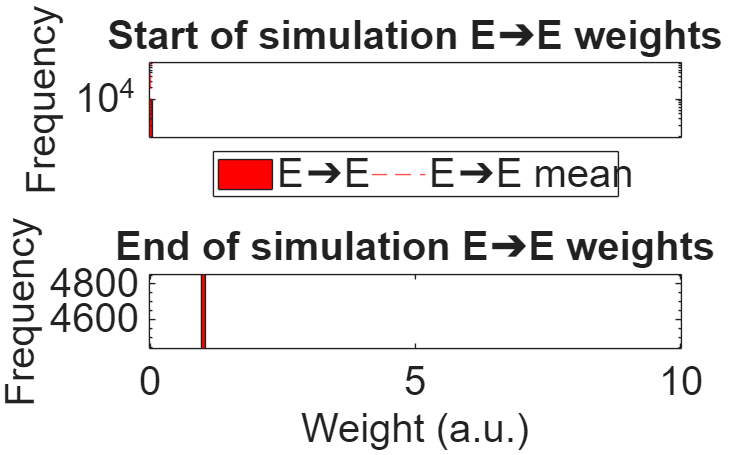

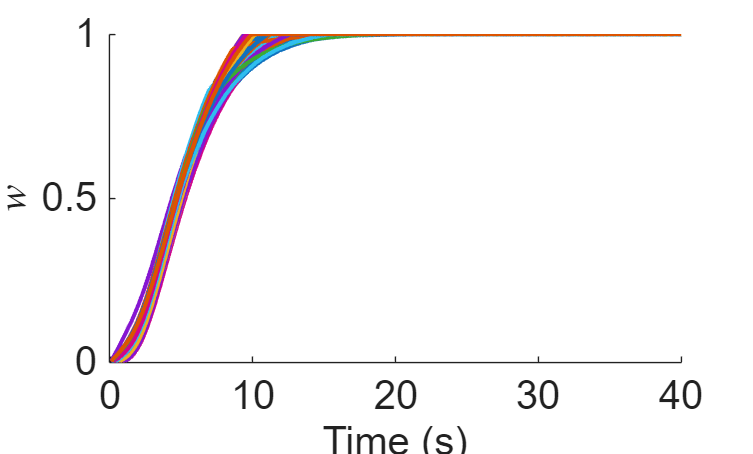

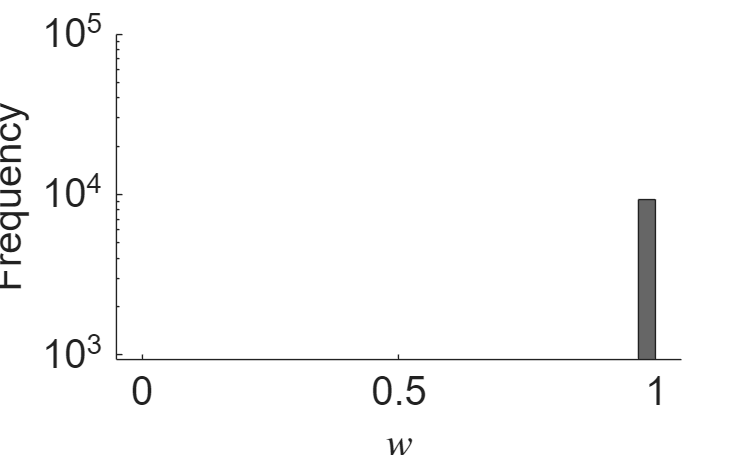

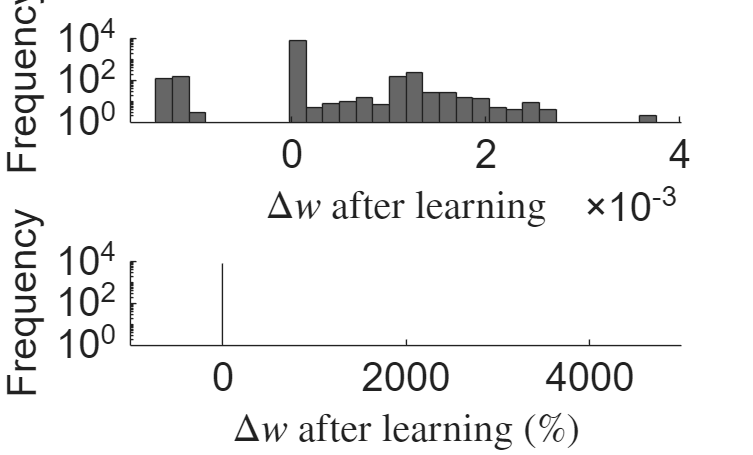

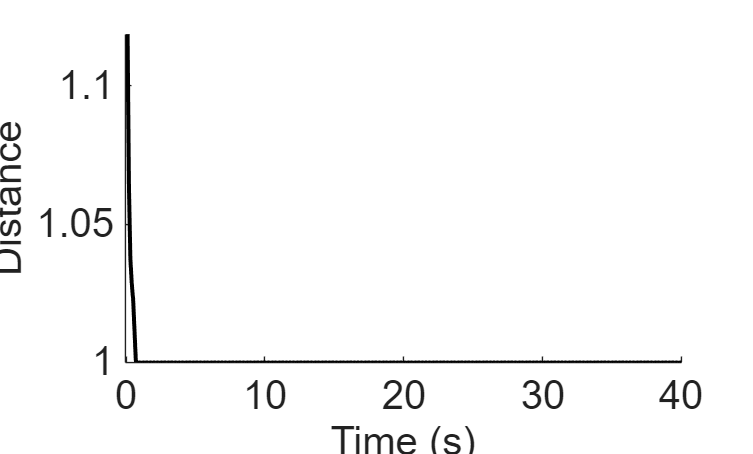

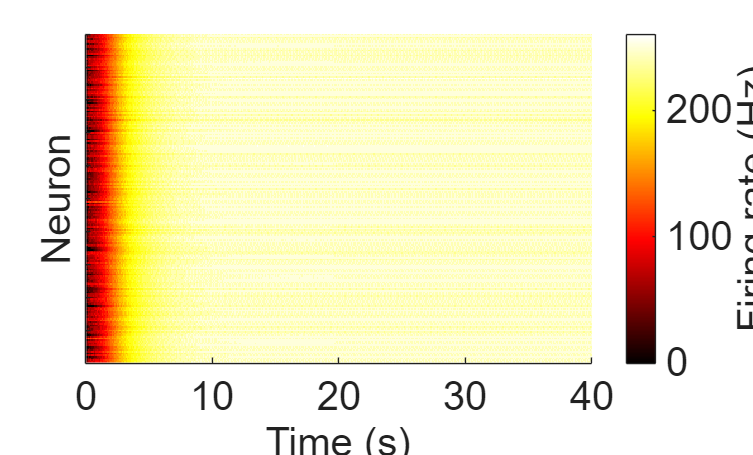

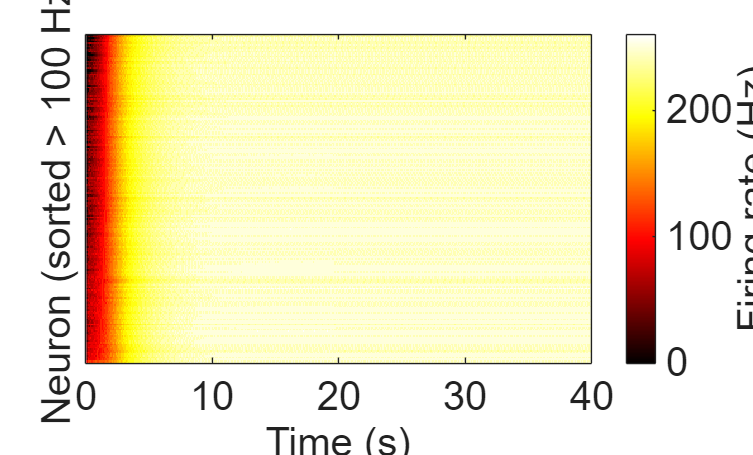

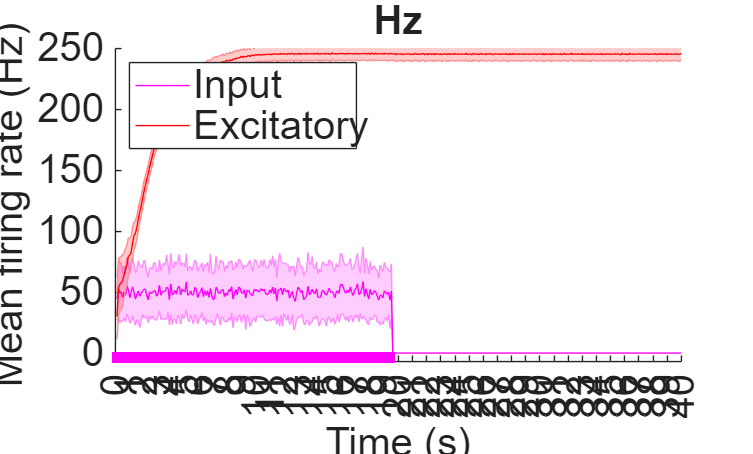

Error using  .  (line 231)
Unrecognized table variable name 'Weight'.
Error in  .  (line 90)
                out = edges.(indexOp);
                ^^^^^^^^^^^^^^^^^^^^^^
Error in 

% Plot
tic
pool_single{1}.plot( ...
    true ... % export
    )

toc
